# Exercise: Understanding (Polynomial) Zonotopes

This exercise should provide you with a deeper understanding of (polynomial) zonotopes.

## Tasks

- Run the code and solve all subtasks on the way.

## Zonotopes

As a short recap, here is the definition of zonotopes [1].


$$Z=\left\lbrace c+\sum_{i=1}^q \beta {\;}_i \cdot G_{\left(\cdot ,i\right)} \;|\;\beta_i \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


In CORA, you can initialize a zonotope with

c = [1;-2];             % center
G = [1 0 2; 0 1 1];     % generator matrix
Z = zonotope(c,G)       % constructor

Z =

zonotope:
- dimension: 2

c: 
     1
    -2

G: (3 generators)
     1     0     2
     0     1     1



CORA provides you with many features to visualize a given set. For example:

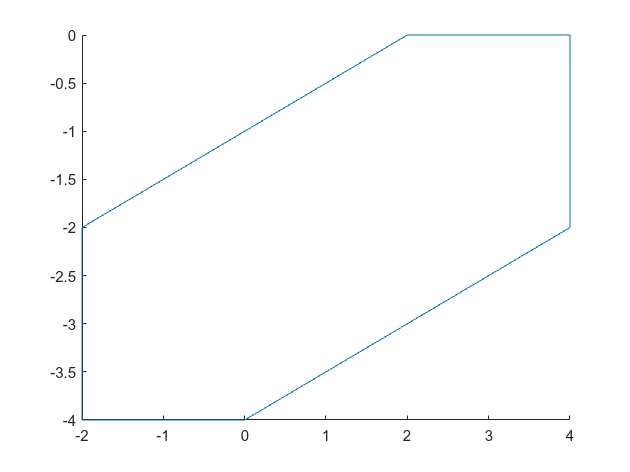

figure; hold on;
plot(Z)

Zonotopes can be seen as Minkowski sum of line segments. In particular, the zonotope above is composed of the following line segments:

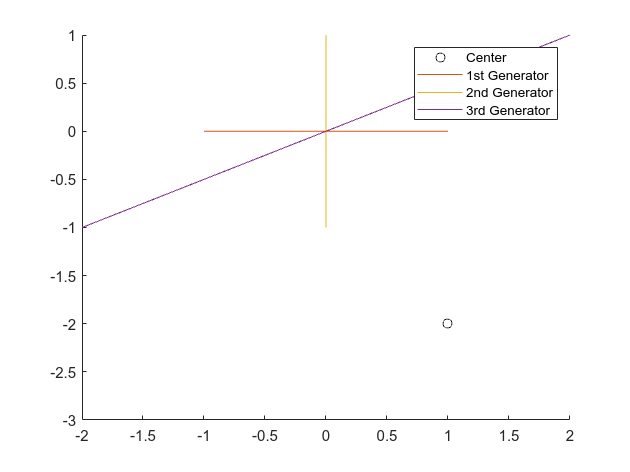

figure; hold on; legend;
scatter(c(1),c(2),'ok','DisplayName','Center')
plot(zonotope([0;0],G(:,1)),1:2,'DisplayName','1st Generator')
plot(zonotope([0;0],G(:,2)),1:2,'DisplayName','2nd Generator')
plot(zonotope([0;0],G(:,3)),1:2,'DisplayName','3rd Generator')
ylim([-3;1])

The plot function also takes additional parameter to customize plotting. See also: [https://de.mathworks.com/help/matlab/ref/plot.html](https://de.mathworks.com/help/matlab/ref/plot.html)

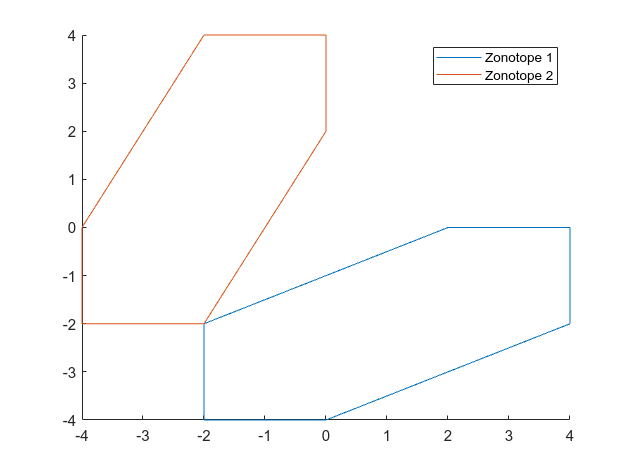

figure; hold on; legend;
plot(Z,[1,2],'DisplayName','Zonotope 1')
plot(Z,[2,1],'DisplayName','Zonotope 2') % here, we reversed the dimensions: 2nd dimension on x-axis, 1st dimension on y-axis

We can randomly draw points from the set with

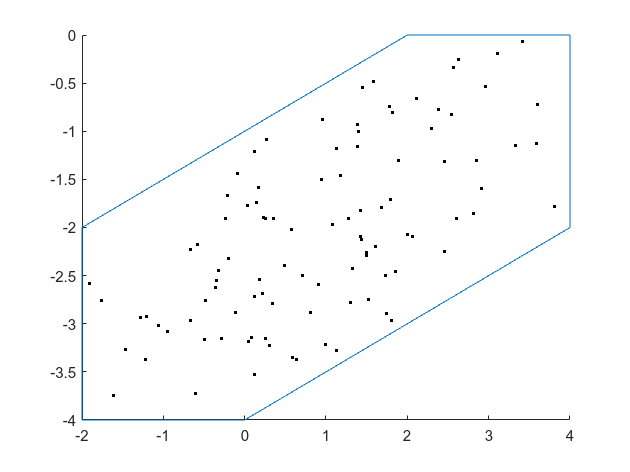

ps = Z.randPoint(100);  % random points

figure; hold on; 
plot(Z);
scatter(ps(1,:),ps(2,:),'.k');

**Task 4.1: **

You are given the following zonotope:


$$Z=\left\lbrace \left\lbrack \begin{array}{c}
3\\
-1
\end{array}\right\rbrack +\beta {\;}_1 \cdot \left\lbrack \begin{array}{c}
2\\
1
\end{array}\right\rbrack +\beta {\;}_2 \cdot \left\lbrack \begin{array}{c}
-1\\
2
\end{array}\right\rbrack +\beta {\;}_3 \cdot \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack \;|\;\beta_i \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


Initialize this zonotope in CORA and plot it in red.

% TODO: initialize zonotope

% TODO: plot zonotope


**Task 4.2:**

To get a better feel for them, try to enclose the following points as tight as possible. All points should touch the border.

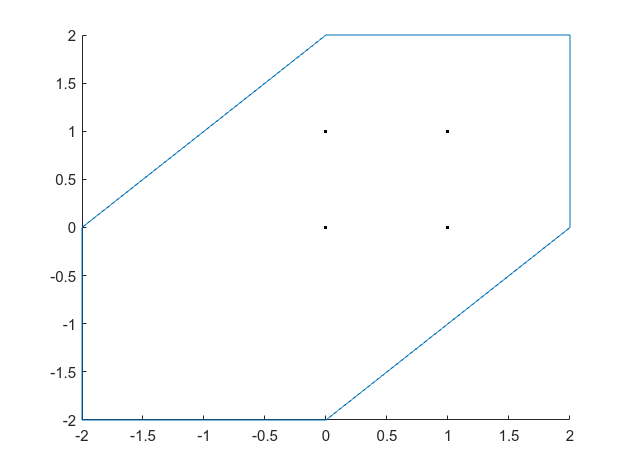

points = [
    0 1 1 0;
    0 0 1 1
];

c = [0;0]; % TODO
G = [      % TODO
    1 0 1; % x-axis
    0 1 1  % y-axis
];
Z = zonotope(c, G);

figure; hold on;
xlim([-1, 2])
ylim([-1, 2])
plot(Z)
scatter(points(1, :), points(2, :), 'k', "Marker", '.')

**Task 4.3: **

Try to enclose the following points as close as possible. All points should touch the border.

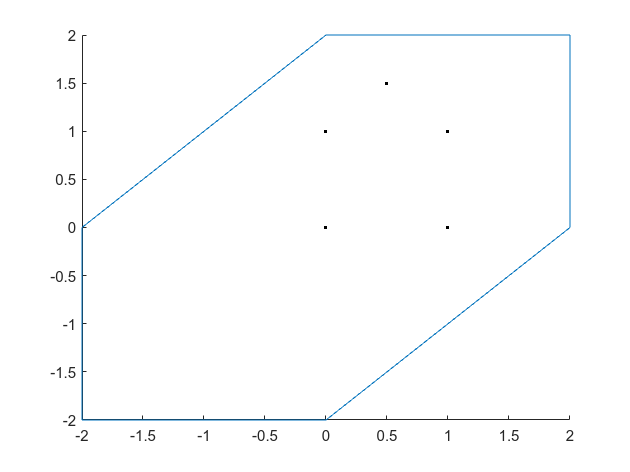

points = [
    0 1 1 0 0.5;
    0 0 1 1 1.5
];

c = [0;0]; % TODO
G = [      % TODO
    1 0 1; % x-axis
    0 1 1  % y-axis
];
Z = zonotope(c, G);

figure; hold on;
xlim([-1, 2])
ylim([-1, 2])
plot(Z)
scatter(points(1, :), points(2, :), 'k', "Marker", '.')

## Polynomial Zonotopes

In this subsection, we will have a deeper look at polynomial zonotopes as they are more expressive than zonotopes and are mainly used during the set propagation through a neural network.

As a short recap, here is the definition of (sparse) polynomial zonotopes [2].


$$\textrm{pZ}=\left\lbrace c+\sum_{i=1}^h \left(\prod_{k=1}^p {\alpha \;}_k^{E_{k,i} } \right)\cdot G_{\left(\cdot ,i\right)} +\sum_{i=1}^q \beta {\;}_i \cdot G_{I\left(\cdot ,i\right)} \;|\;\alpha_{i,\;} \beta_i \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


#### Center c

The "center" defines an anker point of the polynomial zonotope. 

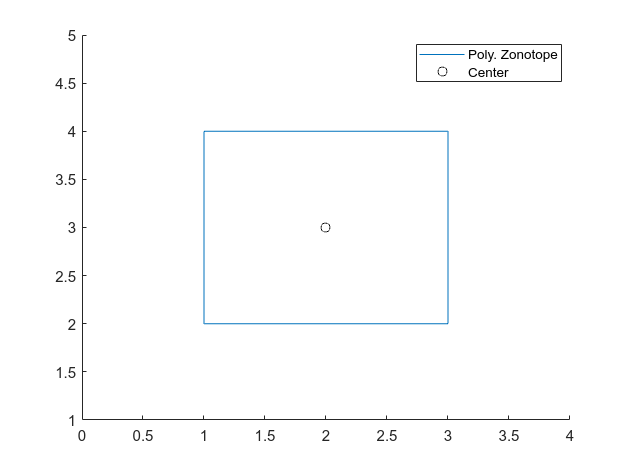

% init polynomial zonotope
c = [2;3];
G = [1 0; 0 1];
GI = [];
E = [1, 0; 0, 1];
pZ = polyZonotope(c, G, GI, E);

figure; hold on;
legend('Location', 'best')
plot(pZ, [1,2], 'DisplayName', 'Poly. Zonotope');
scatter(c(1), c(2), 'k', 'DisplayName', 'Center');
xlim([0;4]);
ylim([1;5]);

Note that this does not have to be 'the center' of the resulting set, but rather any point where we start to construct the polynomial zonotopes from. The center is always in the set.

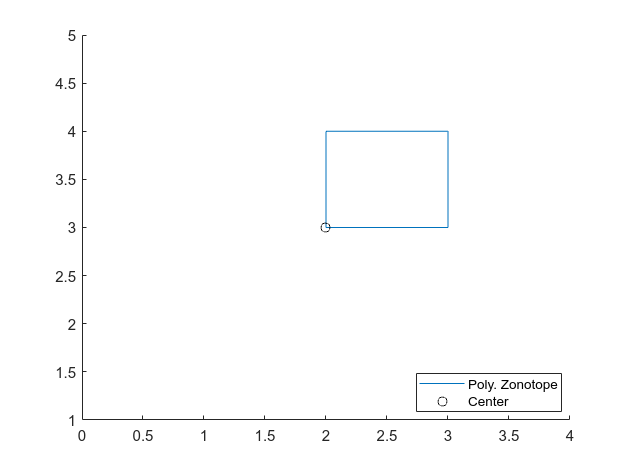

% modify polynomial zonotope
E = [2, 0; 0, 2]; % essentially, this makes alpha \in [0;1] instead of [-1;1]
pZ = polyZonotope(c, G, GI, E);

% plot
figure; hold on;
legend('Location', 'best')
plot(pZ, [1,2], 'DisplayName', 'Poly. Zonotope');
scatter(c(1), c(2), 'k', 'DisplayName', 'Center');
xlim([0;4]);
ylim([1;5]);

Zonotopes are constructed from the Minkowski Sum of lines, i.e. linear polynomials, while polynomial zonotopes are essentially the Minkowski Sum of arbitrary polynomials and also dependencies between generators.

The exponents of these polynomials are modelled in the exponent matrix E. For example, the set


$$\textrm{pZ}=\left\lbrace \left\lbrack \begin{array}{c}
3\\
-1
\end{array}\right\rbrack +\alpha_1 \cdot \left\lbrack \begin{array}{c}
2\\
1
\end{array}\right\rbrack +\alpha_2^4 \cdot \left\lbrack \begin{array}{c}
-1\\
2
\end{array}\right\rbrack \;|\;\alpha_1 ,\alpha_2 \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


is constructed by

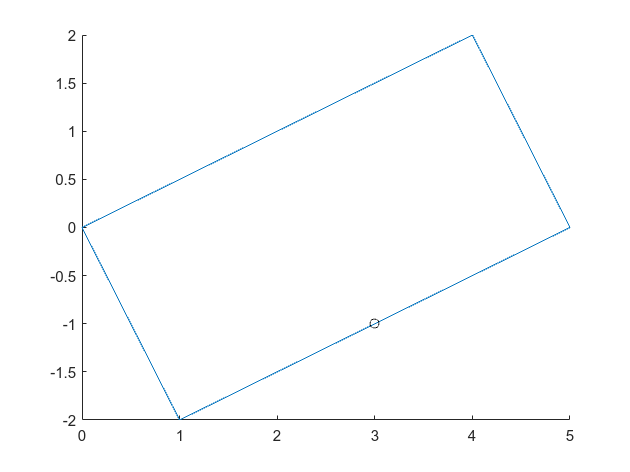

c = [3;-1];
G = [ % (2 generators)
    2 -1; % 1st dimension
    1 2   % 2nd dimension
];
E = [ % (2 generators)
    1 0;  % exponents of alpha_1 for each generator
    0 4;  % exponents of alpha_2 for each generator 
];
pZ = polyZonotope(c,G,[],E);

% plot
figure; hold on;

plot(pZ);
scatter(c(1), c(2), 'k', 'DisplayName', 'Center');

**Task 4.4:**

This set can equally be represented by a zonotope. Construct the zonotope that represents the plotted polynomial zonotope above and plot the zonotope;

% TODO: initialize zonotope

% TODO: plot zonotope


In CORA, you can also transform the polynomial zonotope into a zonotope using

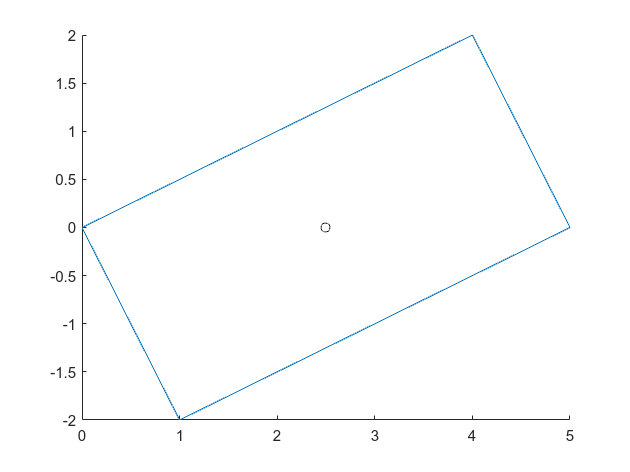

Z = zonotope(pZ);
figure; hold on
plot(Z);
scatter(Z.c(1), Z.c(2), 'k', 'DisplayName', 'Center');

**Task 4.5:**

Note that the center of the resulting zonotope is at a different place, however, Z and pZ represent the same set.

Explain why both represents the same set: ________

*Think about what it means that a given set is represented by a (polynomial) zonotope.*

Of course, using a polynomial zonotope for a set that can equally be represented by a zonotope is not very useful, as zonotopes are much simpler.

However, the expressiveness of polynomial zonotopes is given by its ability to model dependencies between generators. For example, the set


$$\textrm{pZ}=\left\lbrace \left\lbrack \begin{array}{c}
3\\
-1
\end{array}\right\rbrack +\alpha_1 \cdot \left\lbrack \begin{array}{c}
2\\
1
\end{array}\right\rbrack +\alpha_1^4 \cdot \left\lbrack \begin{array}{c}
-1\\
2
\end{array}\right\rbrack \;|\;\alpha_1 \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


is constructed by

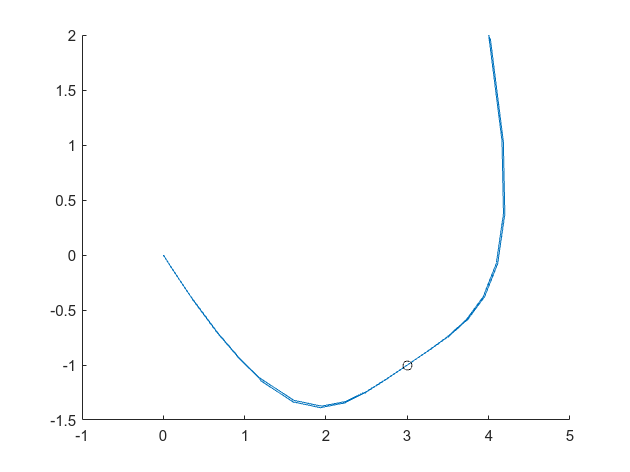

c = [3;-1];
G = [ % (2 generators)
    2 -1; % 1st dimension
    1 2   % 2nd dimension
];
E = [ % (2 generators)
    1 4;  % exponents of alpha_1 for each generator
];
pZ = polyZonotope(c,G,[],E);

% plot
figure; hold on;

plot(pZ);
scatter(c(1), c(2), 'k', 'DisplayName', 'Center');

Such a polynomial zonotope cannot be equally represented by a zonotope:

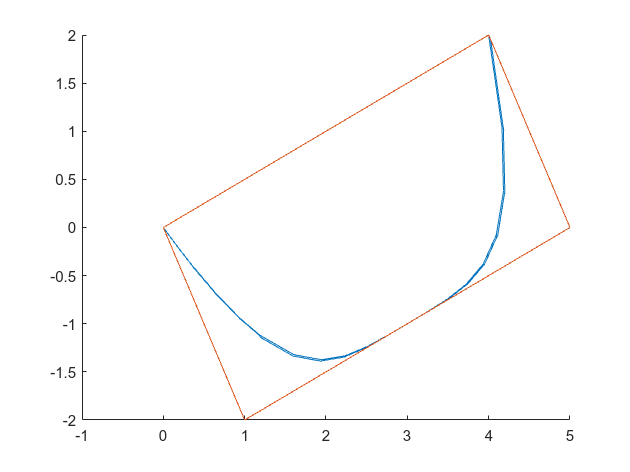

figure; hold on;
plot(pZ,1:2,'DisplayName','Poly. Zonotope');
plot(zonotope(pZ),1:2,'DisplayName','Zonotope');

CORA is designed that all set operations are over-approximative. That is, if a operation cannot be computed exactly, we want to compute a set that includes the actual set. This also happens for the conversion from a polynomial zonotope to a zonotope above, where each point in the polynomial zonotope is also in the zonotope.

**Task 4.6**

Explain why it is a good design choice to make operations over-approximative: _________

**Task 4.7**

Write the set below in math notation:


$$\textrm{pZ}=\left\lbrace \left\lbrack \begin{array}{c}
\\

\end{array}\right\rbrack +\cdots \;|\;\alpha_{i,\;} \beta_i \in \left\lbrack -1;1\right\rbrack \right\rbrace$$


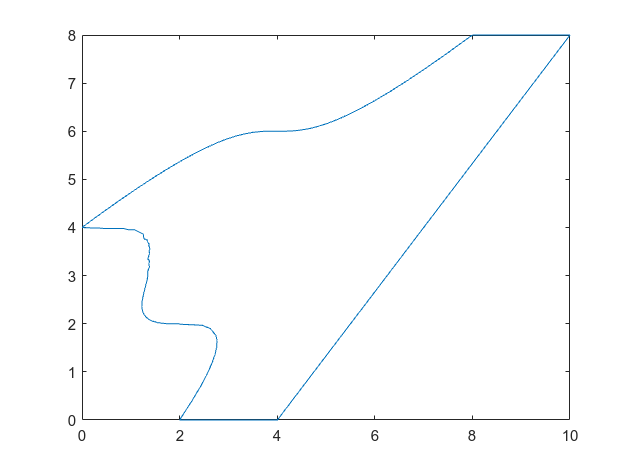

c = [4;4];
G = [2 1 2; 0 2 2];
E = [1 0 3;0 1 1];
GI = [1;0];
pZ = polyZonotope(c,G,GI,E);

% plot
figure;
plot(pZ);

The independent generators $G_I$ are the light-weight generators of polynomial zonotopes. This part of polynomial zonotopes is equivalent to zonotopes, thus, only point-symmetric convex sets can be represented with them.

### Set Operations

#### Linear Map

As with zonotopes. a linear map of a polynomial zonotope pZ with a matrix M is computed by

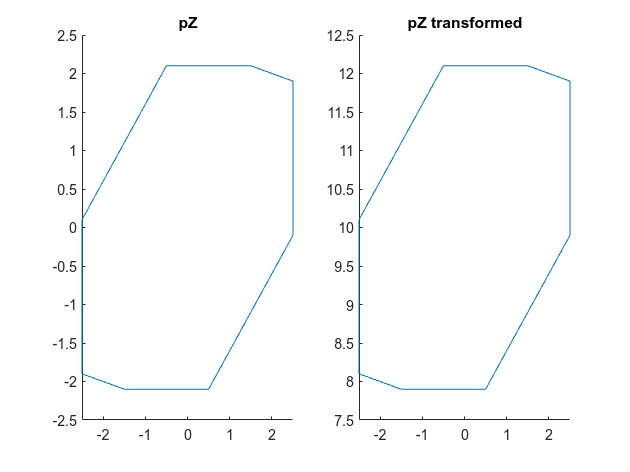

c = [0;0];
G = [
    1 0 1
    0 1 1
];
GI = [-0.5;0.1];
E = eye(3); % identity
pZ = polyZonotope(c, G, GI, E);
M = [
    1, 0; 
    0,1; % multiplies 2nd dim with -1
];
% M = rand(2, 2) % TODO: check your solution of Task 4.8 with a random matrix later
pZ_trans = M * pZ + [0;10];

figure;
subplot(1, 2, 1); hold on;
title("pZ")
plot(pZ, [1, 2]);
subplot(1, 2, 2); hold on;
title("pZ transformed")
plot(pZ_trans, [1, 2]);

**Task 4.8**

Try to reimplement the linear map for polynomial zonotopes. For that, derive the result by checking how a matrix multiplication would affect the definition of polynomial zonotopes.


$$M\cdot \;\left(c+\sum_{i=1}^h \left(\prod_{k=1}^p {\alpha \;}_k^{E_{k,i} } \right)\cdot G_{\left(\cdot ,i\right)} +\sum_{i=1}^q \beta {\;}_i \cdot G_{I\left(\cdot ,i\right)} \right)=\;?$$


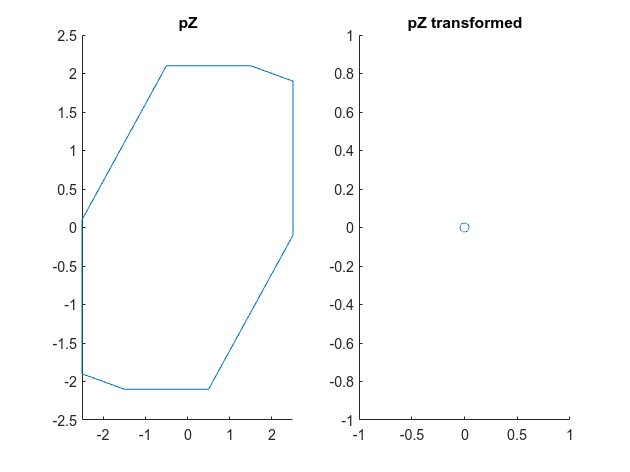

% c, G, GI, E, M is defined above

c_trans = [0;0]; % ?
G_trans = []; % ?
GI_trans = []; % ?
E_trans = []; % ?

pZ_trans = polyZonotope(c_trans, G_trans, GI_trans, E_trans);

figure;
subplot(1, 2, 1); hold on;
title("pZ")
plot(pZ, [1, 2]);
subplot(1, 2, 2); hold on;
title("pZ transformed")
plot(pZ_trans, [1, 2]);

Make sure your solution works for arbitrary M: Recompute this section using a random matrix M (see comment above).

If you have trouble deriving the solution, have a look into the references [2] or check the implementation` (edit polyZonotope/mtimes)`.

#### **Minkowski Sum**

The Minkowski sum of two sets $S_1$ and $S_2$ is defined as the addition of each element of $S_1$ with each element of $S_2$:


$$S_1 +S_2 =\left\lbrace s_1 +s_2 \;|\;s_1 \in S_1 ,s_2 \in S_2 \right\rbrace$$


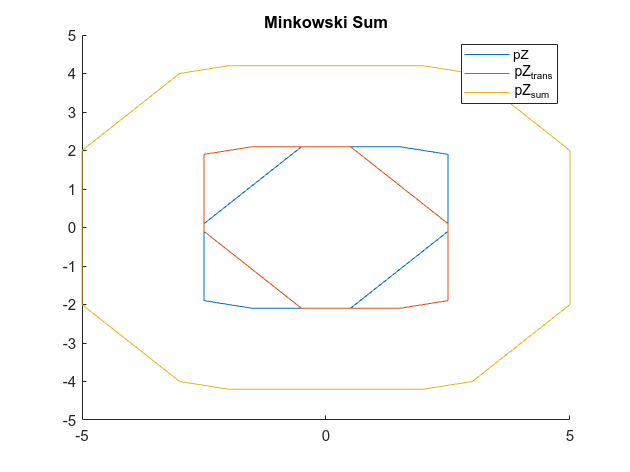

c = [0;0];
G = [
    1 0 1
    0 1 1
];
GI = [-0.5;0.1];
E = eye(3);
pZ = polyZonotope(c, G, GI, E);
M = [
    1, 0; 
    0,-1; % multiplies 2nd dim with -1
];
% M = rand(2, 2) % check your solution of Task 4.9 with a random matrix later
pZ_trans = M * pZ;
pZ_sum = pZ + pZ_trans;

figure; hold on;
plot(pZ, [1, 2], "DisplayName", "pZ");
plot(pZ_trans, [1, 2], "DisplayName", "pZ_{trans}");
plot(pZ_sum, [1, 2], "DisplayName", "pZ_{sum}");
title("Minkowski Sum")
legend(Location="best")

As each element of one set is added to each element of the other set, we can obtain the border of the final set by moving one set along the border of the other set. For example:

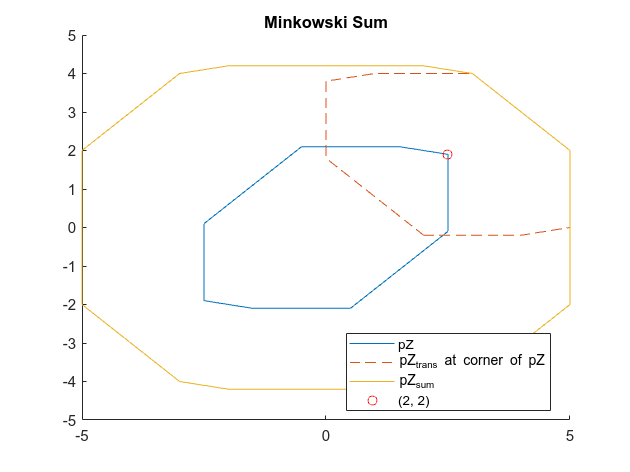

figure; hold on;
plot(pZ, [1, 2], "DisplayName", "pZ");
co = [2.5;1.9];
plot(co + pZ_trans, [1,2], '--', "DisplayName", "pZ_{trans} at corner of pZ");
plot(pZ_sum, [1, 2], "DisplayName", "pZ_{sum}");
scatter(co(1), co(2), 'or', "DisplayName", "(2, 2)")

title("Minkowski Sum")
legend(Location="best")

Note that an element in either set is included in the sum as well, as (0,0) is in both sets. However, this is not true in general.

**Task 4.9**

Try to reimplement the Minkowski sum for polynomial zonotopes. For that, derive the result by checking how the addition would affect the definition of polynomial zonotopes.


$$\;\left(c_1 +\sum_{i=1}^{h_1 } \left(\prod_{k=1}^{p_1 } {\alpha \;}_k^{E_{1,k,i} } \right)\cdot G_{1\left(\cdot ,i\right)} +\sum_{i=1}^{q_1 } \beta {\;}_i \cdot G_{\textrm{I1}\left(\cdot ,i\right)} \right)+\;\left(c_2 +\sum_{i=1}^{h_{2\;} } \left(\prod_{k=1}^{p_2 } {\alpha \;}_k^{E_{2,k,i} } \right)\cdot G_{2\left(\cdot ,i\right)} +\sum_{i=1}^{q_2 } \beta {\;}_i \cdot G_{\textrm{I2}\left(\cdot ,i\right)} \right)=\;?$$


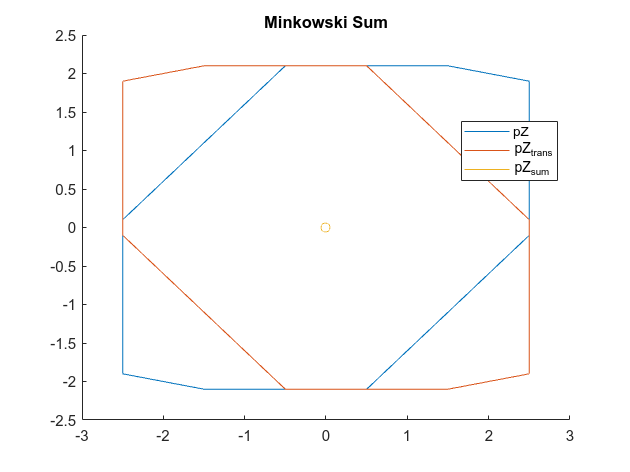

% access elements from pZ, pZ_trans via e.g. pZ.c, pZ.G, pZ.GI, pZ.E
c_sum = [0;0]; % ?
G_sum = []; % ?
GI_sum = []; % ?
E_sum = []; % ?

pZ_sum = polyZonotope(c_sum, G_sum, GI_sum, E_sum);

figure; hold on;
plot(pZ, [1, 2], "DisplayName", "pZ");
plot(pZ_trans, [1, 2], "DisplayName", "pZ_{trans}");
plot(pZ_sum, [1, 2], "DisplayName", "pZ_{sum}");
title("Minkowski Sum")
legend(Location="best")

#### Exact Addition

However, we use polynomial zonotopes with generators that have dependencies between each other.

We computed `pZ_trans` by negating the second dimension (see M). Thus, these two sets should cancel each other out in the second dimension.

Polynomial zonotopes can memorize such dependencies in CORA using the dependent generators.

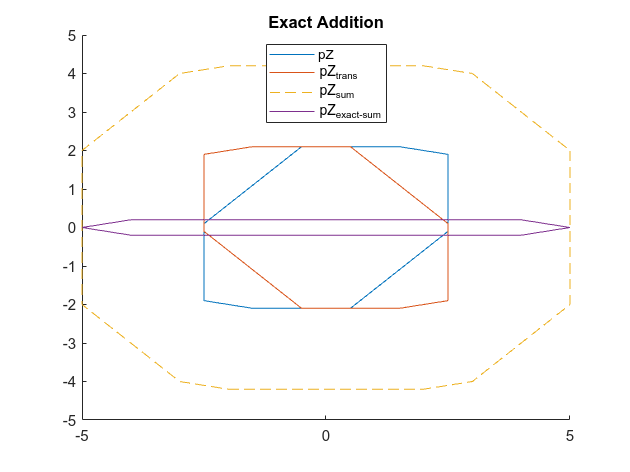

pZ_sum = pZ + pZ_trans;
pZ_exactsum = exactPlus(pZ, pZ_trans);

figure; hold on;
plot(pZ, [1, 2], "DisplayName", "pZ");
plot(pZ_trans, [1, 2], "DisplayName", "pZ_{trans}");
plot(pZ_sum, [1, 2], '--', "DisplayName", "pZ_{sum}");
plot(pZ_exactsum, [1, 2], "DisplayName", "pZ_{exact-sum}");
title("Exact Addition")
legend(Location="best")

However, the resulting set still has some variation in the second dimension. The reason for this is that the independent generators GI are treated, well, independently. Try to set GI above to 0 and check the result.

**Task 4.10**

Try to reimplement the exact addition for polynomial zonotopes. Note that they have a common number of dependent factors p and we know that both use the same $\alpha_k$!


$$\;\left(c_1 +\sum_{i=1}^{h_1 } \left(\prod_{k=1}^p {\alpha \;}_k^{E_{1,k,i} } \right)\cdot G_{1\left(\cdot ,i\right)} +\sum_{i=1}^{q_1 } \beta {\;}_i \cdot G_{\textrm{I1}\left(\cdot ,i\right)} \right)+\;\left(c_2 +\sum_{i=1}^{h_{2\;} } \left(\prod_{k=1}^p {\alpha \;}_k^{E_{2,k,i} } \right)\cdot G_{2\left(\cdot ,i\right)} +\sum_{i=1}^{q_2 } \beta {\;}_i \cdot G_{\textrm{I2}\left(\cdot ,i\right)} \right)=\;?$$


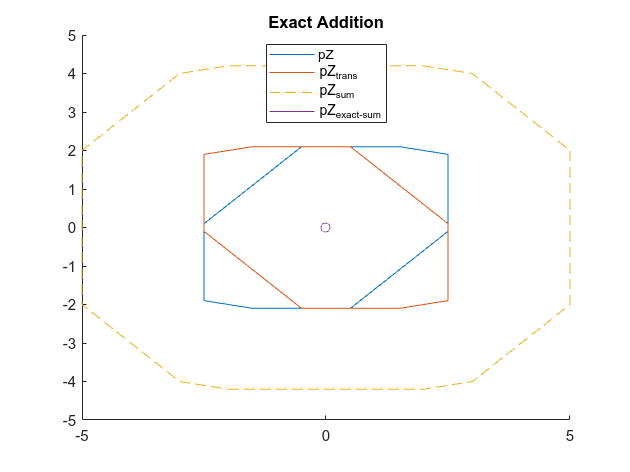

% access elements from pZ, pZ_trans via e.g. pZ.c, pZ.G, pZ.GI, pZ.E
c_exactsum = [0;0]; % ?
G_exactsum = []; % ?
GI_exactsum = []; % ?
E_exactsum = []; % ?

pZ_exactsum = polyZonotope(c_exactsum, G_exactsum, GI_exactsum, E_exactsum);

figure; hold on;
plot(pZ, [1, 2], "DisplayName", "pZ");
plot(pZ_trans, [1, 2], "DisplayName", "pZ_{trans}");
plot(pZ_sum, [1, 2], '--', "DisplayName", "pZ_{sum}");
plot(pZ_exactsum, [1, 2], "DisplayName", "pZ_{exact-sum}");
title("Exact Addition")
legend(Location="best")

CORA keeps track of the dependent factors via an additional id stored in the polynomial zonotope.

disp(pZ.id)

     1
     2
     3



disp(pZ_trans.id)

     1
     2
     3



If we want to investigate the **dependencies between generators**, it is not always easy to draw the resulting set by just looking at the parameters. For example:

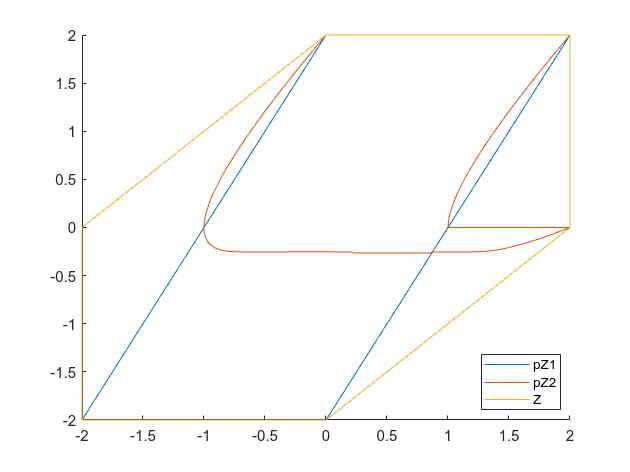

c = [0;0];
G = [
    1 0 1;
    0 1 1
];
GI = [];
expMat1 = [
    1 0 0
    0 1 1 % generator 2 and 3 use the same alpha
];
pZ1 = polyZonotope(c, G, GI, expMat1);
expMat2 = [
    1 0 0
    0 1 2 % changed exponent of alpha_2 for generator 3 from 1 to 2.
];
pZ2 = polyZonotope(c, G, GI, expMat2);
figure; hold on;
legend('Location', 'best')
xlim([-2, 2])
ylim([-2, 2])
plot(pZ1, [1, 2], "DisplayName", "pZ1");
plot(pZ2, [1, 2], "DisplayName", "pZ2");
plot(zonotope(c, G), [1, 2], "DisplayName", "Z");

However, this is also the main advantage of polynomial zonotopes: They can represent non-convex sets and are closed under nonlinear maps.

That is, we can compute the exact solution of a nonlinear map without overapproximations.

For example, the following code computes ${\textrm{pZ}}^2$.

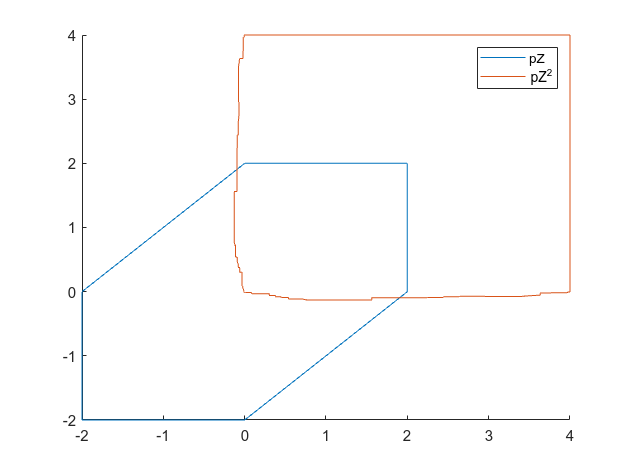

c = [0;0];
G = [
    1 0 1
    0 1 1
];
E = [
    1 0 0;
    0 1 0;
    0 0 1
];
pZ = polyZonotope(c, G, [], eye(3));

pZ2 = quadMap(pZ, {[1,0;0,0], [0,0;0,1]});

figure; hold on;
plot(pZ, [1, 2], "DisplayName", "pZ");
plot(pZ2, [1, 2], "DisplayName", "pZ^2", "Splits", 20);
legend()

disp(pZ2.E)

     2     1     0     0     0
     0     0     2     1     0
     0     1     0     1     2



The plot of ${\textrm{pZ}}^2$ is slightly over-approximative due to recursive splitting in the plotting function, but not the actual represented set.

**Task 4.11: (hard, optional)**

Try to enclose the following points as close as possible.

Note: It is possible to make the set border touch all points. You don't need more than 2 dependent factors.

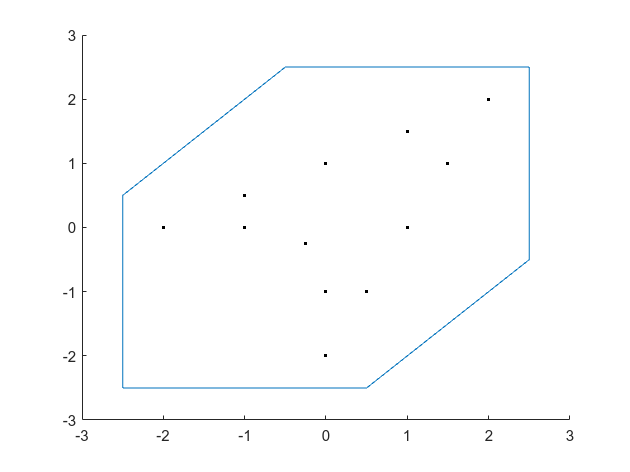

points = [
    0, -2 2 1 0, 1.5 1 0.5 -1 0 -1 -0.25;
    -2 0, 2 0, 1 1 1.5 -1 0.5 -1 0 -0.25
];

c = [0;0]; % TODO
G = [ % TODO
    1 0 1; % x-axis
    0 1 1; % y-axis
];
GI = 0.5 * [ % TODO
    1, 0; % x-axis
    0, 1; % y-axis
];
E = [ % TODO
    1 0 0; % alpha_1
    0 1 0; % alpha_2
    0 0 1; % alpha_3
];
pZ = polyZonotope(c, G, GI, E);

figure; hold on;
xlim([-3, 3])
ylim([-3, 3])
plot(pZ);
scatter(points(1, :), points(2, :), 'k', "Marker", '.')

Export the live script as pdf and send the results back to Tobias ([tobias.ladner@tum.de](mailto:tobias.ladner@tum.de)). Make sure that all tasks are solved and all results are visible in the pdf.

filePath = matlab.desktop.editor.getActiveFilename;
pdfPath = convertStringsToChars(strrep(filePath, ".mlx", ".pdf"));
matlab.internal.liveeditor.openAndConvert (filePath, pdfPath);

 Any question? Just ask!

## References

[1] Girard, A. (2005). Reachability of uncertain linear systems using zonotopes. In *International Workshop on Hybrid Systems: Computation and Control* (pp. 291-305). Berlin, Heidelberg: Springer Berlin Heidelberg.

[2] Kochdumper, N., & Althoff, M. (2020). Sparse polynomial zonotopes: A novel set representation for reachability analysis. *IEEE Transactions on Automatic Control*, *66*(9), 4043-4058.